# GROUP ASSIGNMENT: Data Construction

**Research question:** *Can Finnish municipalities be grouped into meaningful profiles based on demographic,  educational, labor-market, and business characteristics, and how well can these  characteristics predict unemployment risk?*

*As part of the preparation for importing the data into MATLAB, the datasets were preprocessed in Excel and Power Query to keep the MATLAB file clean and make the dataset more suitable for processing. In the original datasets, municipalities were identified by their codes and names, indicators were listed in separate lines, and yearly values were spread across several columns. During the cleaning process in Excel, unnamed columns were named (RegionCode, Region, and IndicatorCode), municipality names, municipality codes, and year values were filled down, and the IndicatorCode column was deleted. Furthermore, the Municipal Key Figures dataset was transformed into long format and variables RegionCode, Region, Information, Year, and Value were defined, while the Establishments dataset was prepared for joining.*

*This MATLAB file presents the process of data construction for the group assignment. The purpose of the script provided in this document is to create a dataset that can be used for further analysis, clustering, and modelling. Therefore, this MATLAB file transforms the data into a form suitable for further processing by means of cluster analysis and modelling. This process includes loading the two datasets, cleaning the data, merging, dealing with missing values, renaming, defining the target and predictors, and then checking variable relationships and outliers.  *

## 1.Data Cleaning

As the first step, the two required datasets need to be loaded and their structure analysed. In this task, the focus is on the Municipal Key Figures dataset and the Establishments of enterprises dataset. The following characteristics are important:

- variable names

- number of rows and year period

- regions or municipalities included in the table

The Municipal key figures dataset is in long format. This means that each row contains one municipality, one year, one variable name, and one value. The Establishments dataset is already closer to modelling format because each row contains one municipality-year observation with business variables.

### **1.1 Load all the datasets and study them**

Load 2 Excel files, "Establishments.xlsx" and "Municipal_key_figures.xlsx".

Now that the datasets are in MATLAB, the data structure is inspected to identify the following elements: number of variables, year periods, and number of regions (municipalities). This information is important for subsequent filtering and merging.

Establishments = readtable("Establishments.xlsx", VariableNamingRule="preserve");
MunicipalKeyFigures = readtable("Municipal_key_figures.xlsx", VariableNamingRule="preserve");
summary(Establishments)


Establishments: 2247×7 table

Variables:

    Year: double
    RegionCode: cell array of character vectors
    Region: cell array of character vectors
    Establishments: double
    Personnel: double
    Turnover: double
    TurnoverPerPerson: double

Statistics for applicable variables:

                         NumMissing      Min         Median           Max              Mean              Std      

    Year                      0          2018          2021             2024              2021            2.0004  
    RegionCode                0                                                                                   
    Region                    0                                           

Establishments

Establishments = 2247×7 table
    Year    RegionCode       Region        Establishments    Personnel     Turnover     TurnoverPerPerson
    ____    __________    _____________    ______________    _________    __________    _________________

    2018    {'KU020'}     {'Akaa'     }         1415            2917        5.27e+05           181       
    2018    {'KU005'}     {'Alajärvi' }         1425            2173      5.1566e+05           237       
    2018    {'KU009'}     {'Alavieska'}          327             420           50474           120       
    2018    {'KU010'}     {'Alavus'   }         1552            3147      5.6092e+05           178       
    2018    {'KU016'}     {'Asikkala' }         1076            1346      2.4747e+05           

summary(MunicipalKeyFigures)


MunicipalKeyFigures: 76342×5 table

Variables:

    RegionCode: cell array of character vectors
    Region: cell array of character vectors
    Information: cell array of character vectors
    Year: double
    Value: double

Statistics for applicable variables:

                   NumMissing       Min         Median           Max             Mean              Std      

    RegionCode           0                                                                                  
    Region               0                                                                                  
    Information          0                                                                                  
    Year                 0 

MunicipalKeyFigures

MunicipalKeyFigures = 76342×5 table
    RegionCode     Region              Information              Year    Value
    __________    ________    ______________________________    ____    _____

    {'KU020'}     {'Akaa'}    {'Persons aged under 15, %'  }    2018    17.7 
    {'KU020'}     {'Akaa'}    {'Persons aged under 15, %'  }    2019    17.2 
    {'KU020'}     {'Akaa'}    {'Persons aged under 15, %'  }    2020    16.5 
    {'KU020'}     {'Akaa'}    {'Persons aged under 15, %'  }    2021    16.3 
    {'KU020'}     {'Akaa'}    {'Persons aged under 15, %'  }    2022    15.7 
    {'KU020'}     {'Akaa'}    {'Persons aged under 15, %'  }    2023    15.3 
    {'KU020'}     {'Akaa'}    {'Persons aged under 15, %'  }    2024      15 
    {'KU020'}     {'Akaa'}    {'Persons aged 15 to 64, %'  }    2018    59.4 
    {'KU020'}

Both of the datasets contain missing values. 

### **1.2 Check RegionCode for joining**

In order to merge the Municipal Key Figures dataset and the Establishments dataset, the existence of municipality codes in both tables must be checked. According to the data processing described in the Excel file, the municipality code is called RegionCode, since it is used as the municipality identifier. Therefore, this variable is the key for joining. All code types were inspected in the dataset, and only the code types starting with KU were selected.

 %% Convert RegionCode and Region to string
Establishments.RegionCode = string(Establishments.RegionCode);

MunicipalKeyFigures.RegionCode = string(MunicipalKeyFigures.RegionCode);

%% 1. Show first RegionCodes in each file
disp(head(Establishments(:, ["RegionCode", "Region"])))

    RegionCode       Region    
    __________    _____________

     "KU020"      {'Akaa'     }
     "KU005"      {'Alajärvi' }
     "KU009"      {'Alavieska'}
     "KU010"      {'Alavus'   }
     "KU016"      {'Asikkala' }
     "KU018"      {'Askola'   }
     "KU019"      {'Aura'     }
     "KU035"      {'Brändö'   }



disp(head(MunicipalKeyFigures(:, ["RegionCode", "Region"])))

    RegionCode     Region 
    __________    ________

     "KU020"      {'Akaa'}
     "KU020"      {'Akaa'}
     "KU020"      {'Akaa'}
     "KU020"      {'Akaa'}
     "KU020"      {'Akaa'}
     "KU020"      {'Akaa'}
     "KU020"      {'Akaa'}
     "KU020"      {'Akaa'}



% Count unique RegionCodes in each file

EstCodes = unique(Establishments.RegionCode);
MunCodes = unique(MunicipalKeyFigures.RegionCode);
disp(numel(EstCodes))

   321



disp(numel(MunCodes))

   574



% Count municipality codes only, meaning codes starting with KU
estMunicipalityCodes = EstCodes(startsWith(EstCodes, "KU"))

estMunicipalityCodes = 320×1 string array
    "KU005"
    "KU009"
    "KU010"
    "KU016"
    "KU018"
    "KU019"
    "KU020"
    "KU035"
    "KU043"
    "KU046"
    "KU047"
    "KU049"
    "KU050"
    "KU051"
    "KU052"
    "KU060"
    "KU061"
    "KU062"
    "KU065"
    "KU069"
    "KU071"
    "KU072"
    "KU074"
    "KU075"
    "KU076"
    "KU077"
    "KU078"
    "KU079"
    "KU081"
    "KU082"


munMunicipalityCodes = MunCodes(startsWith(MunCodes, "KU"))

munMunicipalityCodes = 308×1 string array
    "KU005"
    "KU009"
    "KU010"
    "KU016"
    "KU018"
    "KU019"
    "KU020"
    "KU035"
    "KU043"
    "KU046"
    "KU047"
    "KU049"
    "KU050"
    "KU051"
    "KU052"
    "KU060"
    "KU061"
    "KU062"
    "KU065"
    "KU069"
    "KU071"
    "KU072"
    "KU074"
    "KU075"
    "KU076"
    "KU077"
    "KU078"
    "KU079"
    "KU081"
    "KU082"


% Keep only municipality codes beginning with KU
Establishments = Establishments(startsWith(Establishments.RegionCode, "KU"), :);
MunicipalKeyFigures = MunicipalKeyFigures(startsWith(MunicipalKeyFigures.RegionCode, "KU"), :);

% Check unique municipality codes after filtering
EstMunicipalityCodes = unique(Establishments.RegionCode)

EstMunicipalityCodes = 320×1 string array
    "KU005"
    "KU009"
    "KU010"
    "KU016"
    "KU018"
    "KU019"
    "KU020"
    "KU035"
    "KU043"
    "KU046"
    "KU047"
    "KU049"
    "KU050"
    "KU051"
    "KU052"
    "KU060"
    "KU061"
    "KU062"
    "KU065"
    "KU069"
    "KU071"
    "KU072"
    "KU074"
    "KU075"
    "KU076"
    "KU077"
    "KU078"
    "KU079"
    "KU081"
    "KU082"


MunMunicipalityCodes = unique(MunicipalKeyFigures.RegionCode)

MunMunicipalityCodes = 308×1 string array
    "KU005"
    "KU009"
    "KU010"
    "KU016"
    "KU018"
    "KU019"
    "KU020"
    "KU035"
    "KU043"
    "KU046"
    "KU047"
    "KU049"
    "KU050"
    "KU051"
    "KU052"
    "KU060"
    "KU061"
    "KU062"
    "KU065"
    "KU069"
    "KU071"
    "KU072"
    "KU074"
    "KU075"
    "KU076"
    "KU077"
    "KU078"
    "KU079"
    "KU081"
    "KU082"


**Observations: **The Municipal Key Figures dataset contained municipalities as well as other higher-level regional aggregations. In total, there were 574 distinct region codes, among which only 308 region codes starting with KU corresponded to municipality codes. The Establishments dataset also had some other region code types, and there were 320 region codes starting with KU. However, since only municipalities were needed in the dataset, all rows except the ones having KU at the beginning of the RegionCode variable were excluded.

% Keep only the common years available in both datasets
Establishments = Establishments(Establishments.Year >= 2018 & Establishments.Year <= 2024, :)

Establishments = 2240×7 table
    Year    RegionCode       Region        Establishments    Personnel     Turnover     TurnoverPerPerson
    ____    __________    _____________    ______________    _________    __________    _________________

    2018     "KU020"      {'Akaa'     }         1415            2917        5.27e+05           181       
    2018     "KU005"      {'Alajärvi' }         1425            2173      5.1566e+05           237       
    2018     "KU009"      {'Alavieska'}          327             420           50474           120       
    2018     "KU010"      {'Alavus'   }         1552            3147      5.6092e+05           178       
    2018     "KU016"      {'Asikkala' }         1076            1346      2.4747e+05           

MunicipalKeyFigures = MunicipalKeyFigures(MunicipalKeyFigures.Year >= 2018 & MunicipalKeyFigures.Year <= 2024, :)

MunicipalKeyFigures = 40964×5 table
    RegionCode     Region              Information              Year    Value
    __________    ________    ______________________________    ____    _____

     "KU020"      {'Akaa'}    {'Persons aged under 15, %'  }    2018    17.7 
     "KU020"      {'Akaa'}    {'Persons aged under 15, %'  }    2019    17.2 
     "KU020"      {'Akaa'}    {'Persons aged under 15, %'  }    2020    16.5 
     "KU020"      {'Akaa'}    {'Persons aged under 15, %'  }    2021    16.3 
     "KU020"      {'Akaa'}    {'Persons aged under 15, %'  }    2022    15.7 
     "KU020"      {'Akaa'}    {'Persons aged under 15, %'  }    2023    15.3 
     "KU020"      {'Akaa'}    {'Persons aged under 15, %'  }    2024      15 
     "KU020"      {'Akaa'}    {'Persons aged 15 to 64, %'  }    2018    59.4 
     "KU020" 

### **1.3 Reshaping the Municipal_key_figures**

The Municipal Key Figures data were in long format, i.e. each line contained information about one municipality, one year, one indicator title, and one value. Thus, before merging with the Establishments data, the Municipal Key Figures data had to be reshaped into wide format. The unstack function was used to reshape the data so that each selected indicator would be in a separate column.

Municipal_key = unstack(MunicipalKeyFigures, 'Value', 'Information');

summary(Municipal_key)


Municipal_key: 2156×22 table

Variables:

    RegionCode: string
    Region: cell array of character vectors
    Year: double
    DegreeOfUrbanisation__: double
    EconomicDependencyRatio: double
    EmployedLabourForceResidentInTheArea: double
    EmployeesWorkingInTheirMunicipalityOfResidence_ShareOfEmployedPersons__: double
    EmploymentRateOfPersonsAged20To64__: double
    ForeignCitizens__: double
    Household_dwellingUnitsLivingInRentalDwellings__: double
    IntermunicipalMigrationGain_loss_Persons: double
    PersonsAged15To64__: double
    PersonsAged64OrOver__: double
    PersonsAgedUnder15__: double
    PersonsWithTertiaryLevelQualifications_ShareOfPersonsAged15OrOver__: double
    PopulationChan

## **2. Join Data Using RegionCode and Year**

Since the Municipal Key Figures dataset had been cleaned, filtered, and reshaped, the next step was to join the files together. The Municipal Key Figures dataset and the Establishments dataset were merged by means of RegionCode and Year, since RegionCode uniquely identifies a municipality, while Year helps to match the same municipalities in the same years. Some municipality codes from the Establishments dataset were excluded during the inner join procedure.

finalData = innerjoin(Municipal_key, Establishments,'Keys', {'RegionCode','Year'})

finalData = 2156×27 table
    RegionCode    Region_Municipal_key    Year    DegreeOfUrbanisation__    EconomicDependencyRatio    EmployedLabourForceResidentInTheArea    EmployeesWorkingInTheirMunicipalityOfResidence_ShareOfEmployedPersons__    EmploymentRateOfPersonsAged20To64__    ForeignCitizens__    Household_dwellingUnitsLivingInRentalDwellings__    IntermunicipalMigrationGain_loss_Persons    PersonsAged15To64__    PersonsAged64OrOver__    PersonsAgedUnder15__    PersonsWithTertiaryLevelQualifications_ShareOfPersonsAged15OrOver__    PopulationChangeFromThePreviousYear__    ShareOfJobsInPrimaryProduction__    ShareOfJobsInSecondaryProduction__    ShareOfJobsInServices__

disp(finalData.Properties.VariableNames')

    {'RegionCode'                                                             }
    {'Region_Municipal_key'                                                   }
    {'Year'                                                                   }
    {'DegreeOfUrbanisation__'                                                 }
    {'EconomicDependencyRatio'                                                }
    {'EmployedLabourForceResidentInTheArea'                                   }
    {'EmployeesWorkingInTheirMunicipalityOfResidence_ShareOfEmployedPersons__'}
    {'EmploymentRateOfPersonsAged20To64__'                                    }
    {'ForeignCitizens__'                                                      }
    {'Household_dwellingUnitsLivingInRentalDwellings__'                       }
    {'IntermunicipalMigrationGain_loss_Persons'                               }
    {'PersonsAged15To64__'                                                    }
    {'PersonsAged64OrOver__'            

**Observations: **As a result of joining the datasets, the file contained 308 municipalities and 27 variables. Despite the fact that the Establishments dataset had 320 municipality codes with KU at the beginning, there were only 308 such codes in the Municipal Key Figures dataset. This means that during the merging process some municipality codes from the Establishments dataset were excluded. The variables were named according to their original names in the Statistics Finland database; thus, they had to be renamed to shorter names in order to simplify coding and modelling.

### **2.1 Rename variables.**

Since the variables' names in the data are too long for analysis, coding, and modelling, most of them are renamed.

finalData = renamevars(finalData, ...
    {'RegionCode', ...
     'Region_Municipal_key', ...
     'Year', ...
     'DegreeOfUrbanisation__', ...
     'EconomicDependencyRatio', ...
     'EmployedLabourForceResidentInTheArea', ...
     'EmployeesWorkingInTheirMunicipalityOfResidence_ShareOfEmployedPersons__', ...
     'EmploymentRateOfPersonsAged20To64__', ...
     'ForeignCitizens__', ...
     'Household_dwellingUnitsLivingInRentalDwellings__', ...
     'IntermunicipalMigrationGain_loss_Persons', ...
     'PersonsAged15To64__', ...
     'PersonsAged64OrOver__', ...
     'PersonsAgedUnder15__', ...
     'PersonsWithTertiaryLevelQualifications_ShareOfPersonsAged15OrOver__', ...
     'PopulationChangeFromThePreviousYear__', ...
     'ShareOfJobsInPrimaryProduction__', ...
     'ShareOfJobsInSecondaryProduction__', ...
     'ShareOfJobsInServices__', ...
     'ShareOfPersonsAged15OrOverWithAtLeastUpperSecondaryQualifications__', ...
     'ShareOfUnemployedPersonsInTheLabourForce__', ...
     'WorkplaceSelf_sufficiency', ...
     'Establishments', ...
     'Personnel', ...
     'Turnover', ...
     'TurnoverPerPerson'}, ...
    {'MunicipalityCode', ...
     'Municipality', ...
     'Year', ...
     'UrbanShare', ...
     'DependencyRatio', ...
     'EmployedPeople', ...
     'WorkInOwnArea', ...
     'EmploymentRate', ...
     'ForeignCitizens', ...
     'RentalHousingShare', ...
     'NetMigration', ...
     'WorkingAgeShare', ...
     'OlderShare64', ...
     'YouthShare15', ...
     'TertiaryShare', ...
     'PopulationChange', ...
     'PrimaryJobs', ...
     'SecondaryJobs', ...
     'ServiceJobs', ...
     'UpperSecondaryShare', ...
     'UnemploymentRate', ...
     'WorkplaceSelfSufficiency', ...
     'Establishments', ...
     'Personnel', ...
     'Turnover', ...
     'TurnoverPerPerson'});
finalData

finalData = 2156×27 table
    MunicipalityCode    Municipality     Year    UrbanShare    DependencyRatio    EmployedPeople    WorkInOwnArea    EmploymentRate    ForeignCitizens    RentalHousingShare    NetMigration    WorkingAgeShare    OlderShare64    YouthShare15    TertiaryShare    PopulationChange    PrimaryJobs    SecondaryJobs    ServiceJobs    UpperSecondaryShare    UnemploymentRate    WorkplaceSelfSufficiency    Region_Establishments    Establishments    Personnel     Turnover     TurnoverPerPerson
    ________________<

## 3. Handling Missing Data

After the merging process and renaming the variables, the next step was to detect missing values in the dataset. Missing-value detection is important because missing values may distort the results of any analysis and modelling procedure used afterwards.

% use summary to check data struture and missing values
summary(finalData)


finalData: 2156×27 table

Variables:

    MunicipalityCode: string
    Municipality: cell array of character vectors
    Year: double
    UrbanShare: double
    DependencyRatio: double
    EmployedPeople: double
    WorkInOwnArea: double
    EmploymentRate: double
    ForeignCitizens: double
    RentalHousingShare: double
    NetMigration: double
    WorkingAgeShare: double
    OlderShare64: double
    YouthShare15: double
    TertiaryShare: double
    PopulationChange: double
    PrimaryJobs: double
    SecondaryJobs: double
    ServiceJobs: double
    UpperSecondaryShare: double
    UnemploymentRate: double
    

**Observations: ** Five workplace-structure variables in the dataset had 308 missing values each. In other words, each of these variables was completely empty for one full year. In addition, a very small number of missing values remained in the Establishments variables after the merging process. The main missing-data problem came from 2024, because those workplace variables were not available for that year.

% check missing values by year for the variables with missing values
varsWithMissing = [
    "WorkInOwnArea"
    "PrimaryJobs"
    "SecondaryJobs"
    "ServiceJobs"
    "WorkplaceSelfSufficiency"
    "Personnel"
    "Turnover"
    "TurnoverPerPerson"
];

for i = 1:numel(varsWithMissing)
    varName = varsWithMissing(i);

    fprintf("\nMissing values by year for %s:\n", varName)

    for y = unique(finalData.Year)'
        missingInYear = sum(ismissing(finalData.(varName)(finalData.Year == y)));
        fprintf("%d: %d missing\n", y, missingInYear)
    end
end


Missing values by year for WorkInOwnArea:


2018: 0 missing
2019: 0 missing
2020: 0 missing
2021: 0 missing
2022: 0 missing
2023: 0 missing
2024: 308 missing



Missing values by year for PrimaryJobs:


2018: 0 missing
2019: 0 missing
2020: 0 missing
2021: 0 missing
2022: 0 missing
2023: 0 missing
2024: 308 missing



Missing values by year for SecondaryJobs:


2018: 0 missing
2019: 0 missing
2020: 0 missing
2021: 0 missing
2022: 0 missing
2023: 0 missing
2024: 308 missing



Missing values by year for ServiceJobs:


2018: 0 missing
2019: 0 missing
2020: 0 missing
2021: 0 missing
2022: 0 missing
2023: 0 missing
2024: 308 missing



Missing values by year for WorkplaceSelfSufficiency:


2018: 0 missing
2019: 0 missing
2020: 0 missing
2021: 0 missing
2022: 0 missing
2023: 0 missing
2024: 308 missing



Missing values by year for Personnel:


2018: 1 missing
2019: 0 missing
2020: 0 missing
2021: 0 missing
2022: 0 missing
2023: 0 missing
2024: 0 missing



Missing values by year for Turnover:


2018: 1 missing
2019: 0 missing
2020: 0 missing
2021: 0 missing
2022: 0 missing
2023: 0 missing
2024: 0 missing



Missing values by year for TurnoverPerPerson:


2018: 1 missing
2019: 0 missing
2020: 0 missing
2021: 0 missing
2022: 0 missing
2023: 0 missing
2024: 0 missing


#### **Remove the missing values**

% Remove first the whole 2024 data from the dataset
finalData = finalData(finalData.Year <= 2023, :);
% remove other missing values
finalData = rmmissing(finalData);

% check the dataset again
summary(finalData)


finalData: 1847×27 table

Variables:

    MunicipalityCode: string
    Municipality: cell array of character vectors
    Year: double
    UrbanShare: double
    DependencyRatio: double
    EmployedPeople: double
    WorkInOwnArea: double
    EmploymentRate: double
    ForeignCitizens: double
    RentalHousingShare: double
    NetMigration: double
    WorkingAgeShare: double
    OlderShare64: double
    YouthShare15: double
    TertiaryShare: double
    PopulationChange: double
    PrimaryJobs: double
    SecondaryJobs: double
    ServiceJobs: double
    UpperSecondaryShare: double
    UnemploymentRate: double
    

The dataset is now complete and contains no missing values. It covers the period from 2018 to 2023.

## **4. Define Target and Predictor Variable**

After preprocessing, the next step in the analysis is variable selection. Since the goal of this task is to analyse Finnish municipalities and later perform prediction of municipal unemployment risk, we should choose predictors that can describe the main characteristics of Finnish municipalities, potentially related to unemployment. In other words, the final dataset contains variables describing demographics, education, labour market, workplace structure, migration, housing, and businesses in a municipality.

The chosen target variable for this analysis is `UnemploymentRate`, since the supervised modelling task is devoted to the prediction of municipal unemployment risk. As for predictors, **demographic variables** (`YouthShare15`, `OlderShare64`, and `DependencyRatio`) were chosen because the age structure affects labour supply and economic pressure on the working-age population. `PopulationChange` and `NetMigration` were selected since they show whether a municipality grows or loses people. It may reflect its attractiveness and economic potential. Moreover, `ForeignCitizens`, `UrbanShare`, and `RentalHousingShare` were chosen since they reflect settlement structure, mobility, and housing characteristics, potentially related to labour-market characteristics. As for **educational indicators**, `TertiaryShare` and `UpperSecondaryShare` were chosen, as education affects people's employability and skill structure in the local labour force. The **labour-market variables** `EmploymentRate`, `WorkInOwnArea`, and `WorkplaceSelfSufficiency` were chosen because they characterise local employment conditions, showing whether a person works in his or her municipality. At the same time, variables `PrimaryJobs`, `SecondaryJobs`, and `ServiceJobs` reflect the **structure of the economy** of each municipality, showing job opportunities.

Moreover, **business indicators** `Establishments` and `TurnoverPerPerson` were chosen. `Establishments` is a general characteristic reflecting business presence in a municipality, whereas `TurnoverPerPerson` characterises economic activity by comparing turnover of municipalities of different sizes.

%% Define target and candidate predictors

% Target variable for supervised modelling
targetVar = "UnemploymentRate";

% Candidate predictors selected from the research question
Predictors = [
    "UrbanShare"
    "DependencyRatio"
    "EmployedPeople"
    "WorkInOwnArea"
    "EmploymentRate"
    "ForeignCitizens"
    "RentalHousingShare"
    "NetMigration"
    "WorkingAgeShare"
    "OlderShare64"
    "YouthShare15"
    "TertiaryShare"
    "PopulationChange"
    "PrimaryJobs"
    "SecondaryJobs"
    "ServiceJobs"
    "UpperSecondaryShare"
    "WorkplaceSelfSufficiency"
    "Establishments"
    "Personnel"
    "Turnover"
    "TurnoverPerPerson"
];

% Keep only variables that exist in finalData
Predictors = Predictors(ismember(Predictors, finalData.Properties.VariableNames));

% Create predictor table and target vector
predictorTable = finalData(:, Predictors)

predictorTable = 1847×22 table
    UrbanShare    DependencyRatio    EmployedPeople    WorkInOwnArea    EmploymentRate    ForeignCitizens    RentalHousingShare    NetMigration    WorkingAgeShare    OlderShare64    YouthShare15    TertiaryShare    PopulationChange    PrimaryJobs    SecondaryJobs    ServiceJobs    UpperSecondaryShare    WorkplaceSelfSufficiency    Establishments    Personnel     Turnover     TurnoverPerPerson
    __________    _______________    ______________    _____________    ______________    _______________<

targetV = finalData.(targetVar) % UnemploymentRate

targetV =    10.1000
    9.3000
   12.1000
    8.3000
    8.1000
    8.3000
    7.7000
    8.8000
   11.3000
    7.8000
    9.8000
   11.5000
    7.7000
    8.5000
    9.7000


## 5. **Identify Variable Relationships and Remove Highly Correlated Variables**

After preparing the data, handling missing values, and selecting the target and predictor variables, the relationships between predictors had to be inspected in order to avoid duplicates. As often happens in such situations, predictor variables with almost identical content may create redundant information for clustering and modelling. Therefore, it is important to check correlation between variables. Highly correlated variables with a correlation coefficient larger than 0.85 were not automatically excluded. Instead, the decision of which variable to include was made based on its relevance to the problem.

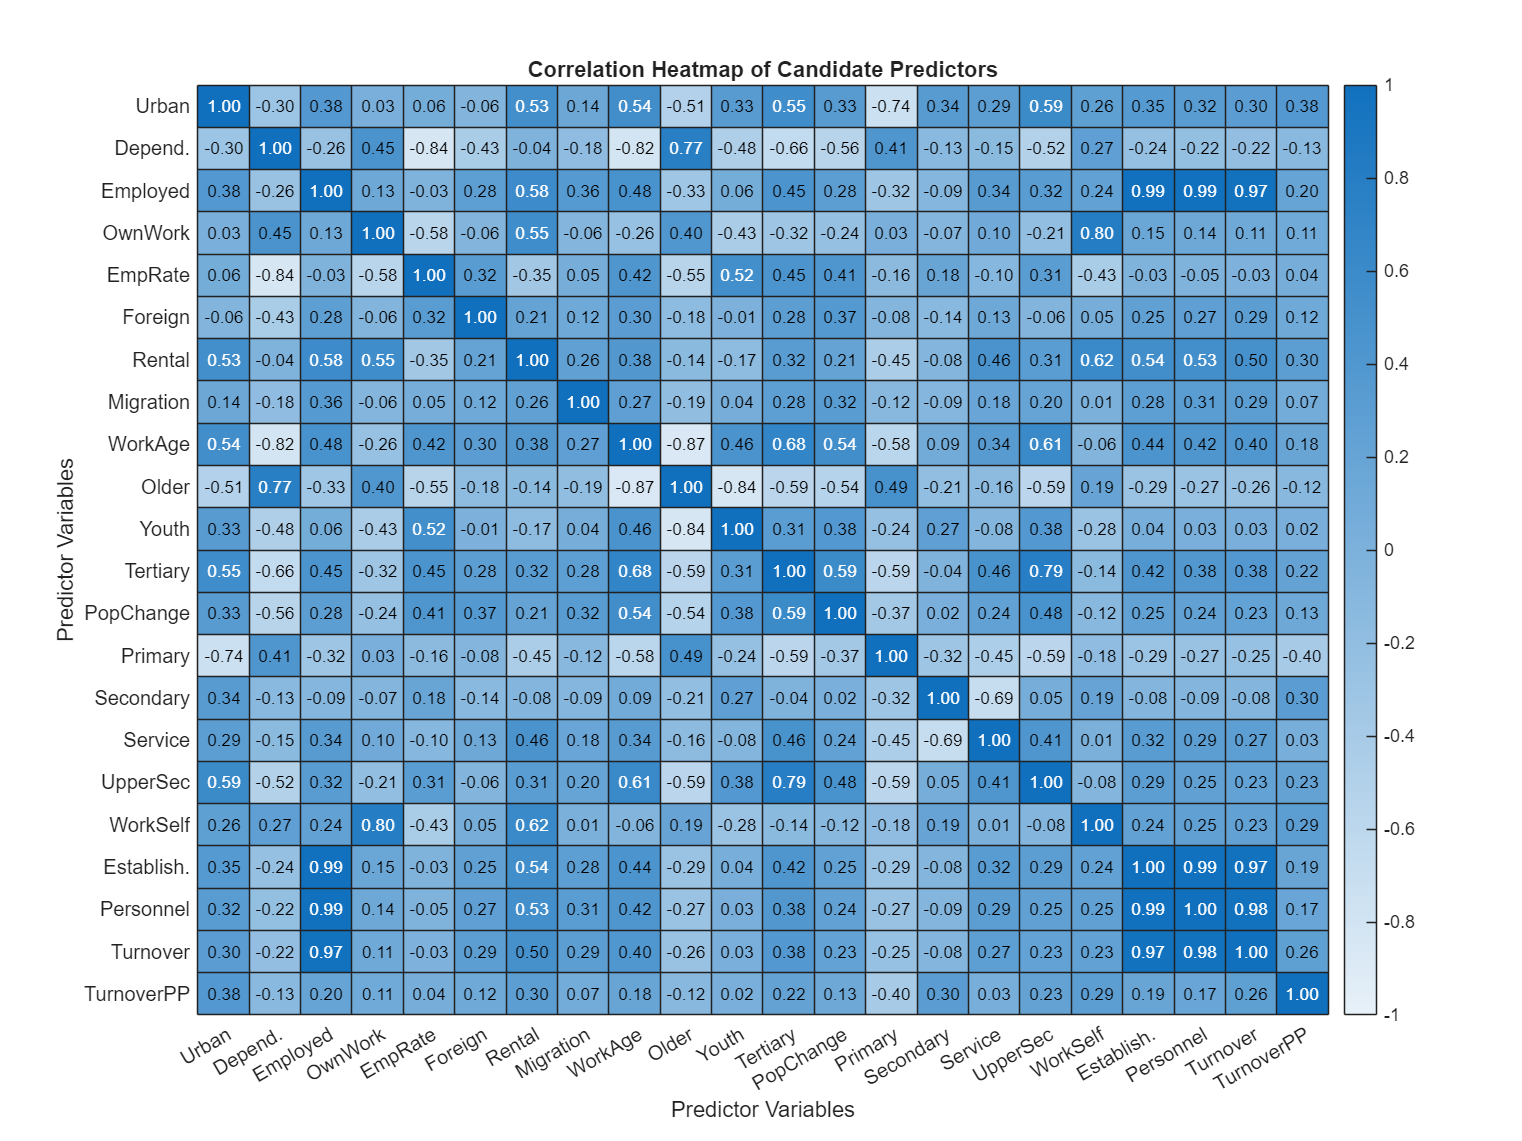

%% Check correlation among candidate predictors

predmatrix = table2array(predictorTable);

R = corr(predmatrix, 'Rows', 'pairwise');


% Shorter labels for readability
shortLabels = [
    "Urban"
    "Depend."
    "Employed"
    "OwnWork"
    "EmpRate"
    "Foreign"
    "Rental"
    "Migration"
    "WorkAge"
    "Older"
    "Youth"
    "Tertiary"
    "PopChange"
    "Primary"
    "Secondary"
    "Service"
    "UpperSec"
    "WorkSelf"
    "Establish."
    "Personnel"
    "Turnover"
    "TurnoverPP"
];

% Keep only labels for variables that actually exist in Predictors
shortLabels = shortLabels(1:numel(Predictors));

% Create larger figure
figure('Position', [100 100 1200 900]);
h = heatmap(shortLabels, shortLabels, R);
h.Title = "Correlation Heatmap of Candidate Predictors";
h.XLabel = "Predictor Variables";
h.YLabel = "Predictor Variables";
h.ColorLimits = [-1 1];
h.CellLabelFormat = "%.2f";

% List highly correlated predictor pairs

threshold = 0.85;

for i = 1:numel(Predictors)
    for j = i+1:numel(Predictors)
        if abs(R(i,j)) >= threshold
            fprintf("%s -- %s : %.2f\n", ...
                Predictors(i), Predictors(j), R(i,j));
        end
    end
end

EmployedPeople -- Establishments : 0.99
EmployedPeople -- Personnel : 0.99
EmployedPeople -- Turnover : 0.97
WorkingAgeShare -- OlderShare64 : -0.87
Establishments -- Personnel : 0.99
Establishments -- Turnover : 0.97
Personnel -- Turnover : 0.98


**Observations: **According to the heatmap, a large number of predictor variables were highly correlated. Positive correlation existed between variables that measure business activity in absolute values. As shown by the correlation coefficients, EmployedPeople, Establishments, Personnel, and Turnover were highly correlated and measured basically the same feature. Negative correlation was observed between WorkingAgeShare and OlderShare64, because they both describe the same characteristic, namely population age structure, but from different angles. The list of highly correlated predictor variables shows the need to consider these predictors carefully when building the model. In particular, it is important to avoid using a large number of redundant predictors with similar content.

%% Select final predictor variables
% Variables removed after checking correlations
RemovedPredictors = [
    "EmployedPeople"
    "Personnel"
    "Turnover"
    "WorkingAgeShare"
];

`RemovedPredictors`:EmployedPeople, Personnel, and Turnover were excluded from the predictor set because they were measured in absolute numbers and had a high correlation with other predictors. WorkingAgeShare was excluded due to high negative correlation with the OlderShare64 predictor, which better reflects municipal demographic structure (ageing and demographic structure). The final predictor set represents demographic structure, education level, migration, housing, labour-market characteristics, workplace structure, and business activity.


% Keep all candidate predictors except removed variables
FinalPredictors = setdiff(Predictors, RemovedPredictors, 'stable');

% Create final predictor table
finalPredictorTable = finalData(:, FinalPredictors)

finalPredictorTable = 1847×18 table
    UrbanShare    DependencyRatio    WorkInOwnArea    EmploymentRate    ForeignCitizens    RentalHousingShare    NetMigration    OlderShare64    YouthShare15    TertiaryShare    PopulationChange    PrimaryJobs    SecondaryJobs    ServiceJobs    UpperSecondaryShare    WorkplaceSelfSufficiency    Establishments    TurnoverPerPerson
    __________    _______________    _____________    ______________    _______________    __________________    ____________    ____________    ____________    ____

% Target variable UnemploymentRate
targetV = finalData.(targetVar)

targetV =    10.1000
    9.3000
   12.1000
    8.3000
    8.1000
    8.3000
    7.7000
    8.8000
   11.3000
    7.8000
    9.8000
   11.5000
    7.7000
    8.5000
    9.7000


**Final dataset structure: **The dataset now has 1847 municipality-year observations, 22 variables, and covers the period 2018-2023. Variables MunicipalityCode, Municipality, and Year were left in the final dataset. However, they are not used as predictors for supervised models, but rather for clustering and time analysis.

## 6. Check Outliers

The next step is to detect outliers. These are extremely large or small values that may distort the model and the entire analysis process. Since municipalities vary significantly in size within Finland, it is clear that some outliers may appear simply because of these differences in size. Municipalities such as Helsinki, Espoo, Tampere, Turku, and others are large cities. They are expected to have higher rates of economic activity and other predictors reflecting population structure and municipal characteristics. However, such municipal units cannot be excluded from further analysis because they are valid observations.

For the identification of outliers and for distinguishing them from mistakes and valid observations, summary statistics and boxplot visualisation were used.

% Summary statistics for final predictors
summary(finalPredictorTable)


finalPredictorTable: 1847×18 table

Variables:

    UrbanShare: double
    DependencyRatio: double
    WorkInOwnArea: double
    EmploymentRate: double
    ForeignCitizens: double
    RentalHousingShare: double
    NetMigration: double
    OlderShare64: double
    YouthShare15: double
    TertiaryShare: double
    PopulationChange: double
    PrimaryJobs: double
    SecondaryJobs: double
    ServiceJobs: double
    UpperSecondaryShare: double
    WorkplaceSelfSufficiency: double
    Establishments: double
    TurnoverPerPerson: double

Statistics for applicable variables:

                                NumMissing        Min         

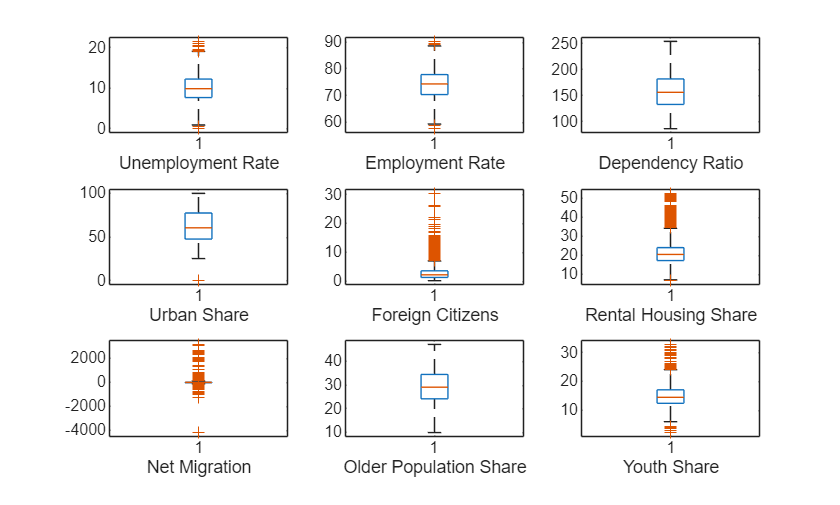

%% Boxplots: Labour market and demographic variables

figure;

subplot(3,3,1)
boxplot(finalData.UnemploymentRate)
xlabel('Unemployment Rate')

subplot(3,3,2)
boxplot(finalData.EmploymentRate)
xlabel('Employment Rate')

subplot(3,3,3)
boxplot(finalData.DependencyRatio)
xlabel('Dependency Ratio')

subplot(3,3,4)
boxplot(finalData.UrbanShare)
xlabel('Urban Share')

subplot(3,3,5)
boxplot(finalData.ForeignCitizens)
xlabel('Foreign Citizens')

subplot(3,3,6)
boxplot(finalData.RentalHousingShare)
xlabel('Rental Housing Share')

subplot(3,3,7)
boxplot(finalData.NetMigration)
xlabel('Net Migration')

subplot(3,3,8)
boxplot(finalData.OlderShare64)
xlabel('Older Population Share')

subplot(3,3,9)
boxplot(finalData.YouthShare15)
xlabel('Youth Share')

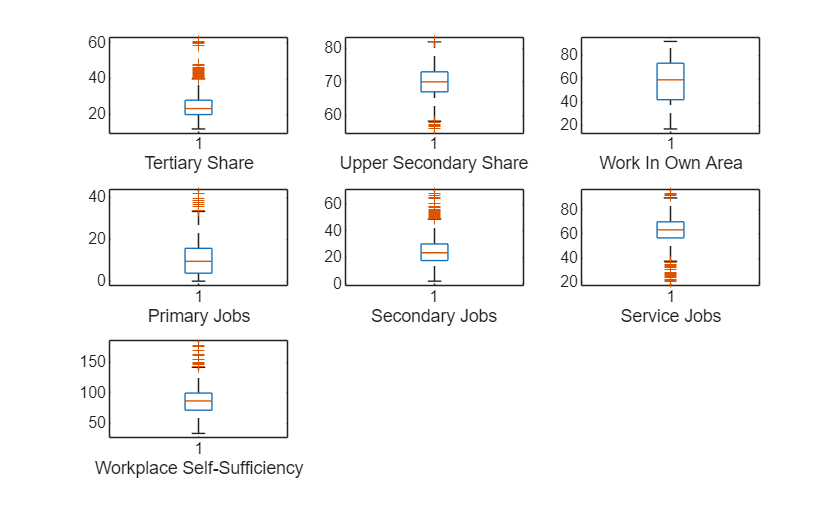

%% Boxplots: Education and workplace structure variables

figure;

subplot(3,3,1)
boxplot(finalData.TertiaryShare)
xlabel('Tertiary Share')

subplot(3,3,2)
boxplot(finalData.UpperSecondaryShare)
xlabel('Upper Secondary Share')

subplot(3,3,3)
boxplot(finalData.WorkInOwnArea)
xlabel('Work In Own Area')

subplot(3,3,4)
boxplot(finalData.PrimaryJobs)
xlabel('Primary Jobs')

subplot(3,3,5)
boxplot(finalData.SecondaryJobs)
xlabel('Secondary Jobs')

subplot(3,3,6)
boxplot(finalData.ServiceJobs)
xlabel('Service Jobs')

subplot(3,3,7)
boxplot(finalData.WorkplaceSelfSufficiency)
xlabel('Workplace Self-Sufficiency')

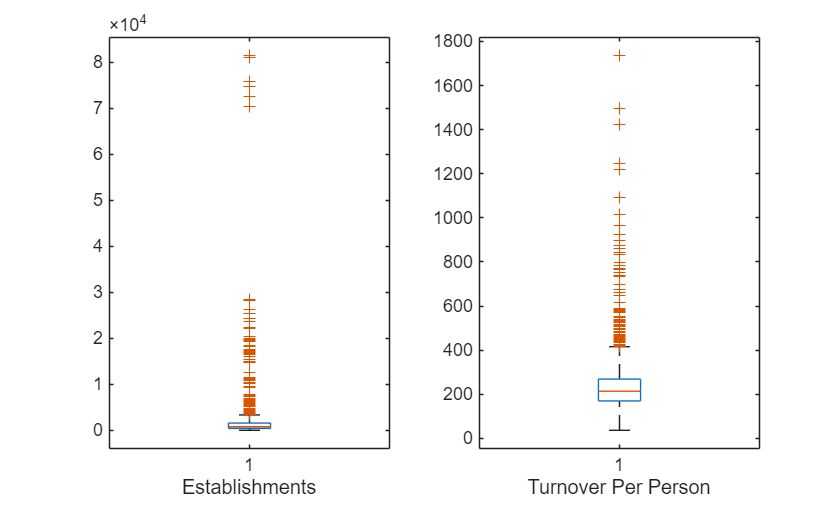

%% Boxplots: Business activity variables

figure;

subplot(1,2,1)
boxplot(finalData.Establishments)
xlabel('Establishments')

subplot(1,2,2)
boxplot(finalData.TurnoverPerPerson)
xlabel('Turnover Per Person')

**Observations: **For the convenience of outlier analysis, the boxplots were divided into groups of variable types. In most cases, labour-market and demographic variables seem reasonable in their variation. Some outliers are visible due to differences in population structure and labour-market conditions between municipalities. Outliers in business activity are more pronounced, especially in Establishments and TurnoverPerPerson.

%% Count outliers

% Variables to check
outlierVars = [FinalPredictors; targetVar];

% Prepare result table
Variable = strings(numel(outlierVars),1);
OutlierCount = zeros(numel(outlierVars),1);
LowerLimit = zeros(numel(outlierVars),1);
UpperLimit = zeros(numel(outlierVars),1);

for i = 1:numel(outlierVars)

    varName = outlierVars(i);
    x = finalData.(varName);

    % detect outliers using quartiles
    [~, outlierIndices, lo, hi] = filloutliers(x, "linear", "quartiles");

    % Store results
    Variable(i) = varName;
    OutlierCount(i) = nnz(outlierIndices);
    LowerLimit(i) = lo;
    UpperLimit(i) = hi;

end

% Create outlier summary table
outlierTable = table(Variable, OutlierCount, LowerLimit, UpperLimit);

% Sort by number of outliers
outlierTable = sortrows(outlierTable, "OutlierCount", "descend")

outlierTable = 19×4 table
             Variable             OutlierCount    LowerLimit    UpperLimit
    __________________________    ____________    __________    __________

    "NetMigration"                    272           -144.5          91.5  
    "Establishments"                  181          -1350.6        3368.4  
    "ForeignCitizens"                 156            -2.15          7.05  
    "RentalHousingShare"              127              7.1          34.3  
    "TurnoverPerPerson"                84             21.5         417.5  
    "UrbanShare"                       59           2.8125        122.31  
    "YouthShare15"                     49             5.35         24.15  
    "SecondaryJobs"                    41          -1.2625        49.037  
    "TertiaryShare"                    31              7.9          39.9  
    "Populat

**Observations: **Most of the outliers appeared in the `NetMigration, Establishments, ForeignCitizens, RentalHousingShare`, and `TurnoverPerPerson`. The large number of outliers is explained by significant differences in population size, degree of urbanisation, migration, and economic activity between municipalities. Outliers were not excluded from further analysis because they reflect the actual difference between large cities and other municipalities rather than mistakes.

%% Create final analytical dataset

identifierVars = [
    "MunicipalityCode"
    "Municipality"
    "Year"
];

% Make sure all variable lists are column vectors
identifierVars = identifierVars(:);
FinalPredictors = FinalPredictors(:);
targetVar = targetVar(:);

% Combine identifiers, final predictors, and target variable
finalVariableList = [
    identifierVars
    FinalPredictors
    targetVar
];

% Create final analytical dataset
finalDataset = finalData(:, finalVariableList);

disp("Final analytical dataset:")

Final analytical dataset:


summary(finalDataset)


finalDataset: 1847×22 table

Variables:

    MunicipalityCode: string
    Municipality: cell array of character vectors
    Year: double
    UrbanShare: double
    DependencyRatio: double
    WorkInOwnArea: double
    EmploymentRate: double
    ForeignCitizens: double
    RentalHousingShare: double
    NetMigration: double
    OlderShare64: double
    YouthShare15: double
    TertiaryShare: double
    PopulationChange: double
    PrimaryJobs: double
    SecondaryJobs: double
    ServiceJobs: double
    UpperSecondaryShare: double
    WorkplaceSelfSufficiency: double
    Establishments: double
    TurnoverPerPerson: do


%% Save final cleaned dataset

writetable(finalDataset, "Municipal_key_figures_final.xlsx", ...
    "WriteMode", "overwritesheet");
writetable(finalDataset, "Municipal_key_figures_final.csv");

disp("Final cleaned dataset saved as Excel and CSV.")

Final cleaned dataset saved as Excel and CSV.
